num=1;
den=[1 10 20];
g=tf(num,den)


g =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.



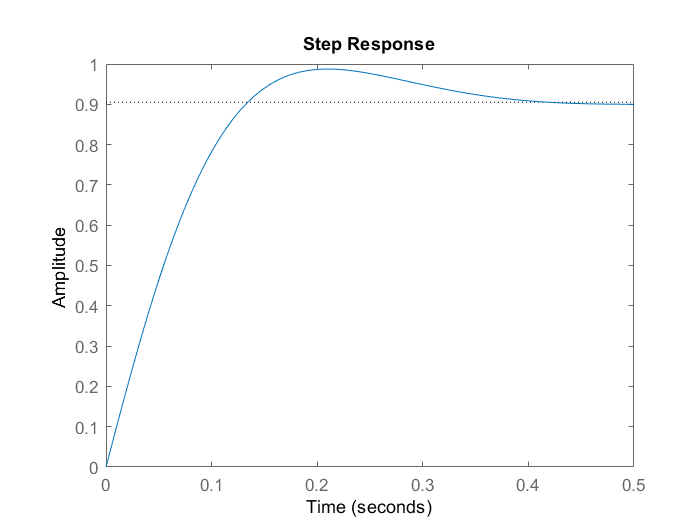

t=feedback(g,1);

kp=200;
ki=0;
kd=10;
cont=pid(kp,ki,kd);
step(feedback(cont*t,1));

stepinfo(feedback(cont*t,1))

ans = struct with fields:
        RiseTime: 0.0983
    SettlingTime: 0.3524
     SettlingMin: 0.8276
     SettlingMax: 0.9874
       Overshoot: 9.1099
      Undershoot: 0
            Peak: 0.9874
        PeakTime: 0.2118


k=dcgain(cont*t);
1/(1+k)

ans = 0.0950